# Simulation Studies on Instrumentation, Circuit Analysis, and Sensor Measurement Methods

Simscape™ enables you to rapidly create models of physical systems within the Simulink® environment. With Simscape, you build physical component models based on physical connections that directly integrate with block diagrams and other modeling paradigms. You model systems such as electric motors, bridge rectifiers, hydraulic actuators, and refrigeration systems, by assembling fundamental components into a schematic. Simscape add-on products provide more complex components and analysis capabilities.

Simscape helps you develop control systems and test system-level performance. You can create custom component models using the MATLAB® based Simscape language, which enables text-based authoring of physical modeling components, domains, and libraries. You can parameterize your models using MATLAB variables and expressions, and design control systems for your physical system in Simulink. To deploy your models to other simulation environments, including hardware-in-the-loop (HIL) systems, Simscape supports C-code generation.

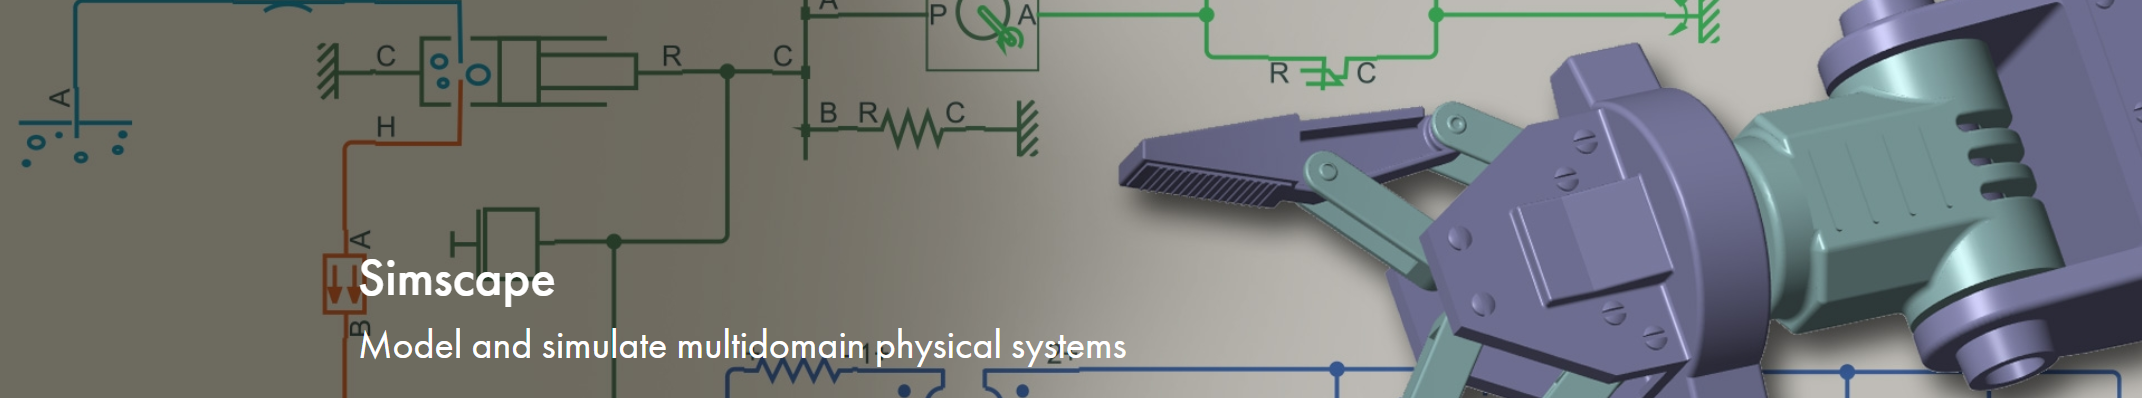

## Laboratory Instrumentation

### Time Scope

features:

- [Triggers](https://www.mathworks.com/help/simulink/ug/scope-trigger-panel.html) — Set triggers to sync repeating signals and pause the display when events occur.

- [Cursor Measurements](https://www.mathworks.com/help/simulink/ug/cursor-measurements-panel.html) — Measure signal values using vertical and horizontal cursors.

- [Signal Statistics](https://www.mathworks.com/help/simulink/ug/signal-statistics-panel.html) — Display the maximum, minimum, peak-to-peak difference, mean, median, and RMS values of a selected signal.

- [Peak Finder](https://www.mathworks.com/help/simulink/ug/peak-finder-panel.html) — Find maxima, showing the *x*-axis values at which they occur.

- [Bilevel Measurements](https://www.mathworks.com/help/simulink/ug/bilevel-measurements-panel.html) — Measure transitions, overshoots, undershoots, and cycles.

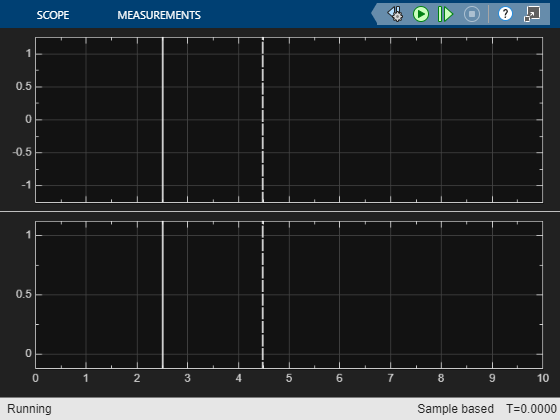

model = 'Scope1';
open_system(model)

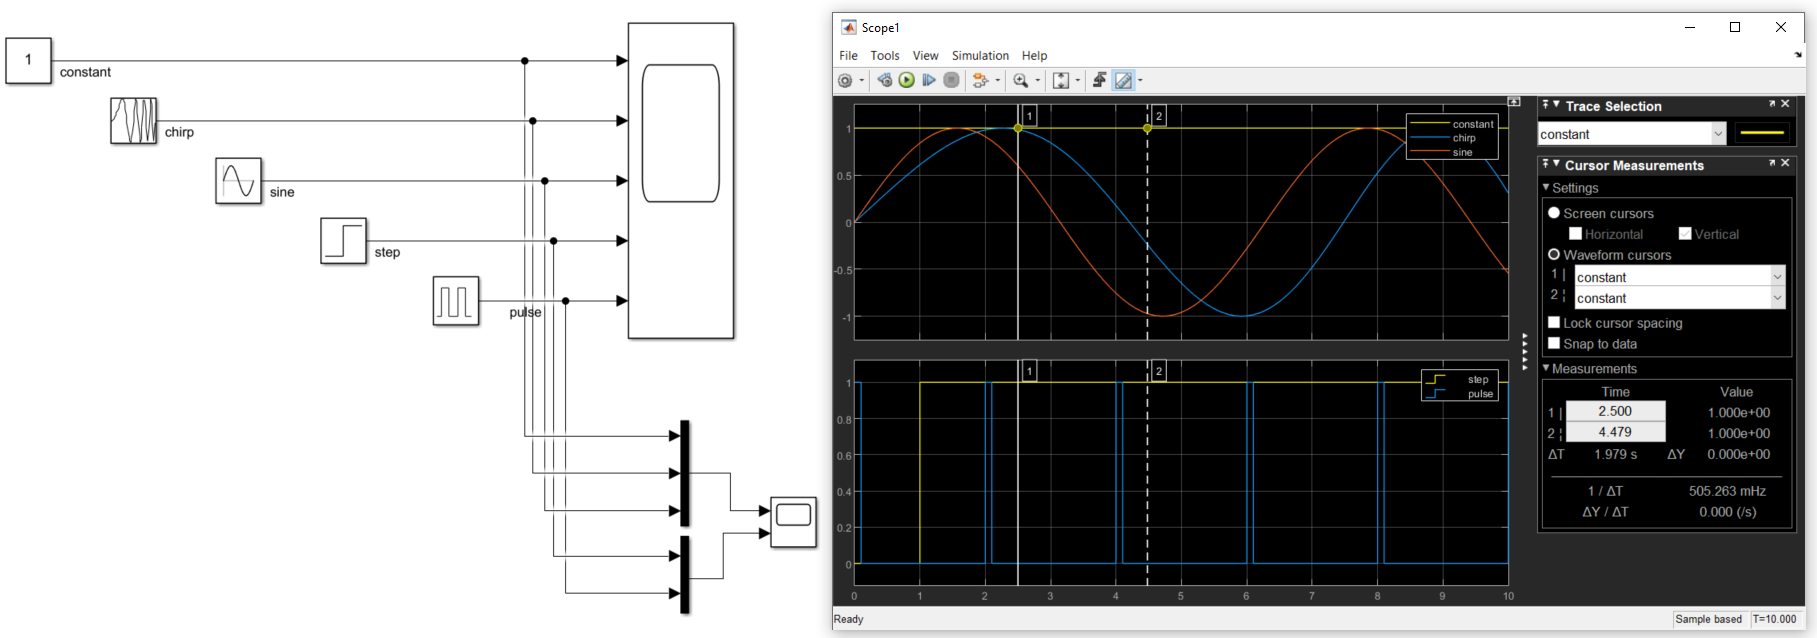

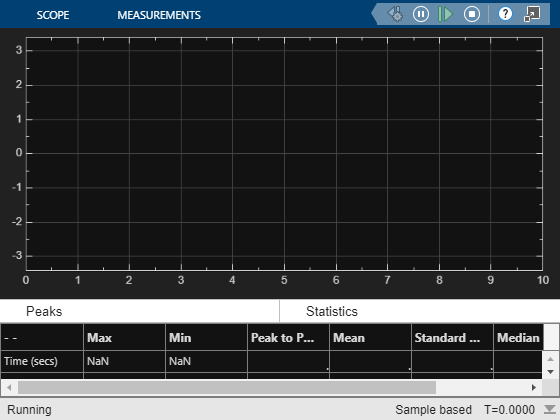

model = 'Scope2';
open_system(model)

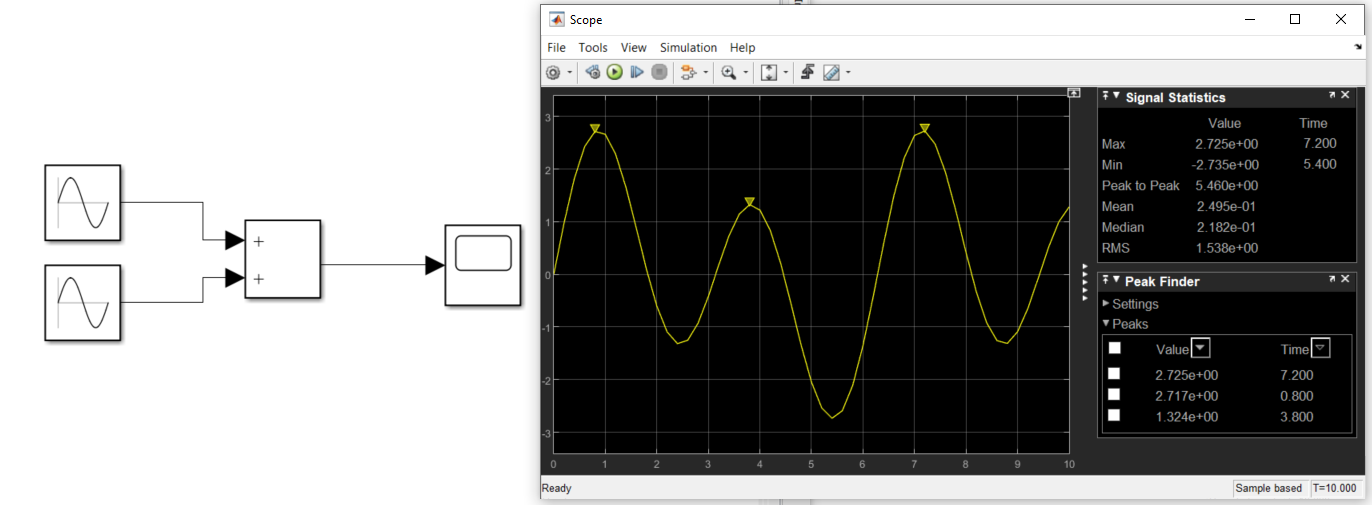

### Waveform Generator

The [Signal Generator block](https://www.mathworks.com/help/simulink/slref/signalgenerator.html) can produce one of four different waveforms:

- sine

- square

- sawtooth

- random

model = 'WaveformGenerator';
open_system(model)

## 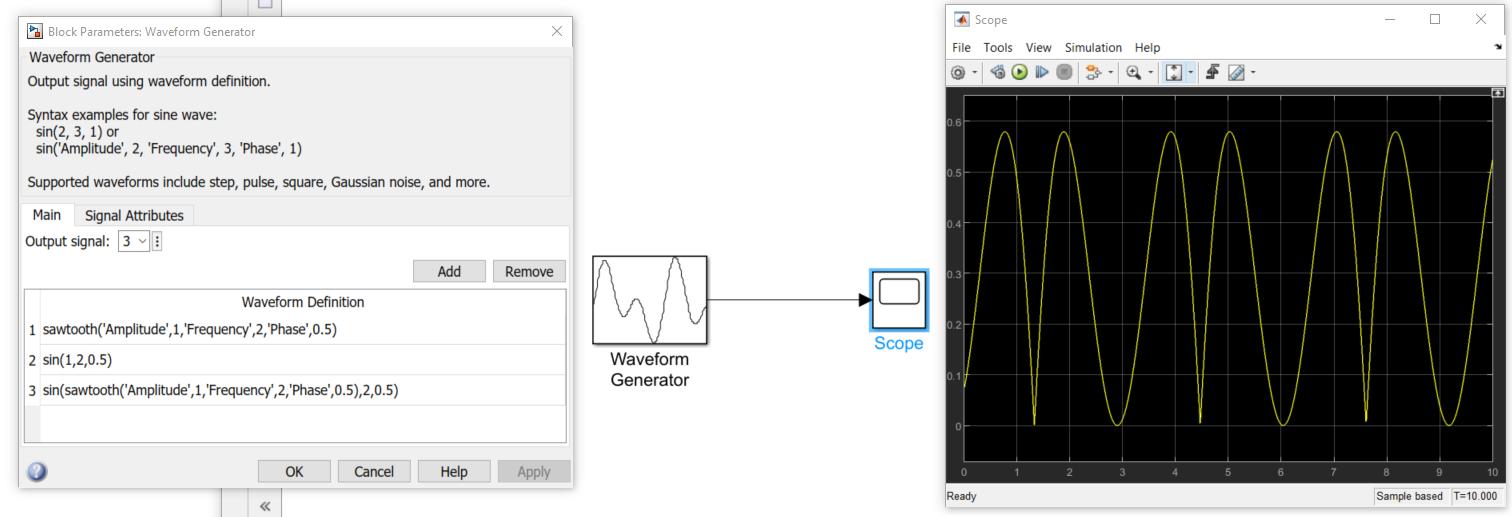

model = 'WaveformGenerator_hitCrossing';
open_system(model)

## 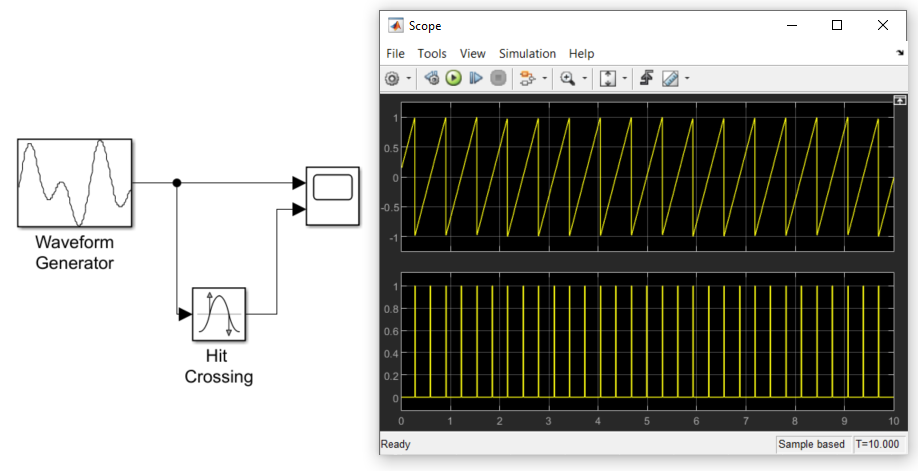

## Basic DC Circuit Computations 

### Series-Parallel Circuit Resistance Computation

In a given electrical circuit the basic circuit computation begins with the equivalent resistance computation of a series parallel network. 

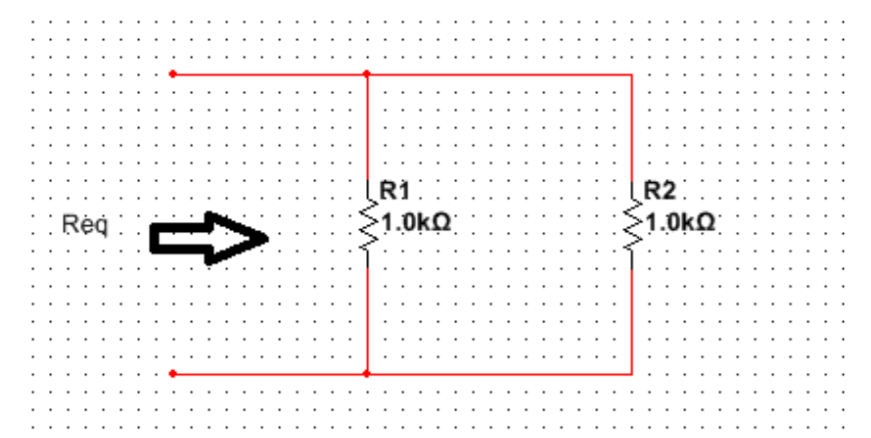

 The equivalent resistance is given by: 


$$R_{\textrm{eq}\;} =\frac{R_1 R_2 }{R_1 +R_2 }$$


R1 = 1000;
R2 = 1000;
R_eq = R1*R2/(R1+R2)

### C Nodal Analysis Computation: 

Nodal analysis provides a general procedure for analyzing circuits using node voltage as the circuit variables. The nodes of the circuit are the places where they are connected together. The circuit shown in figure 3.0 has three nodes. Node 3 is the reference node or the datum node. Analyzing the connected circuit containing n nodes will require n-1 KCL equations. The KCL equations are obtained from each node with exception of the reference node or the datum node. Following are steps to determine the nodal voltages:

- Express element current as function of the nodal voltage 

- Apply KCL to each node with the exception of reference node 

- Solve the resulting simultaneous equations to obtain the unknown voltages. 

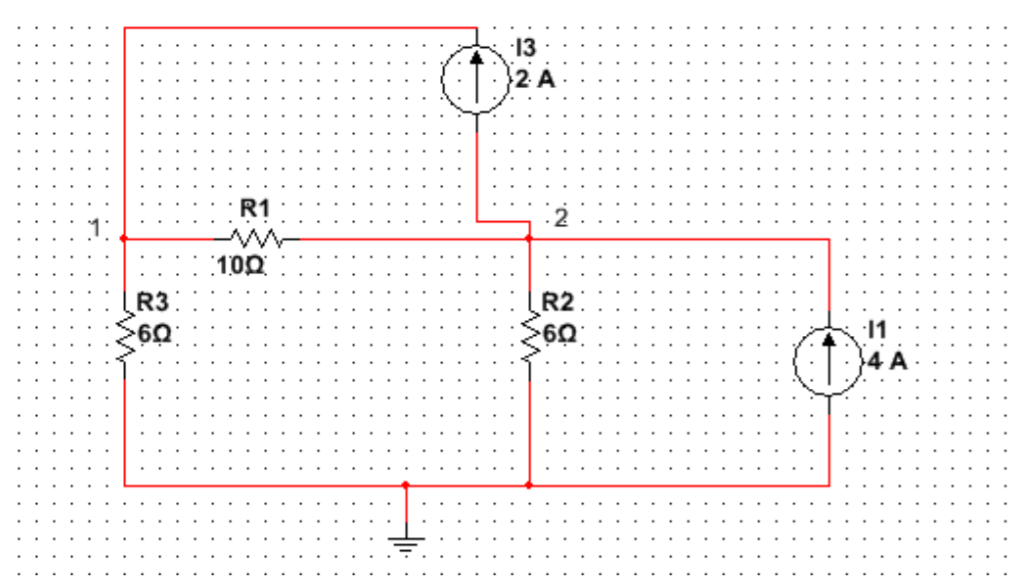

Applying KCL to node 1 of circuit we can obtain the following equations:


$$\textrm{i1}=\textrm{i2}+\textrm{i3}$$



$$2=\frac{\textrm{v1}-0}{6}+\frac{\textrm{v1}-\textrm{v2}}{10}$$


Applying KCL to node 2 of circuit we can obtain the following equations:


$$\textrm{i2}+\textrm{i4}=\textrm{i1}+\textrm{i5}$$



$$\frac{\textrm{v1}-0}{6}+4=2+\frac{\textrm{v2}-0}{5}$$


syms v1 v2
e1 = (v1-0)/6 + (v1-v2)/10 == 2;
e2 = (v1-v2)/10 + 4 == 2 + (v2-0)/6;
s = solve(e1,e2)
[s.v1 s.v2]

### **DC Circuit Modeling with Simscape**

model = 'ElectricCircuitAnalysisinMATLABandSimulink';
open_system(model)

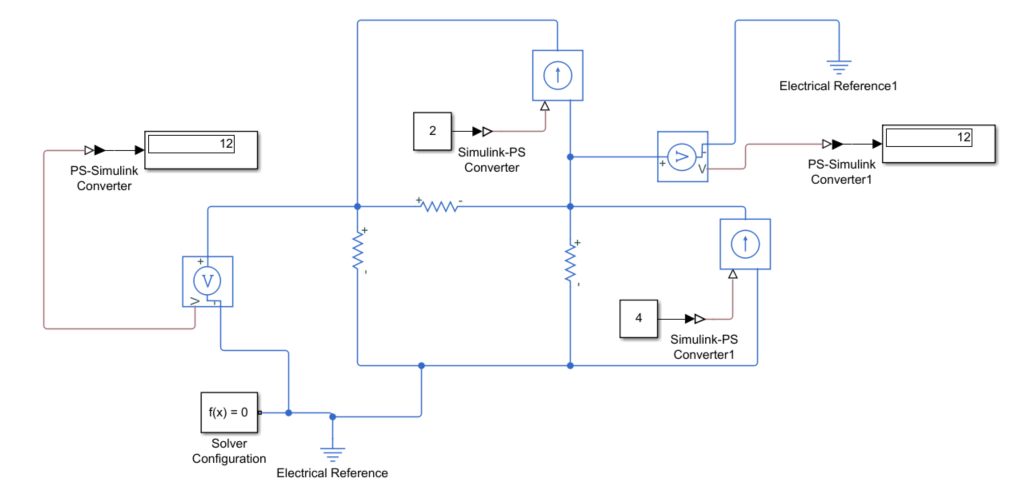

## Measurement Method - Wheatstone Bridge

Example 1

R = 10

R_eq = 500

model = 'WheatstoneBridge';
open_system(model)

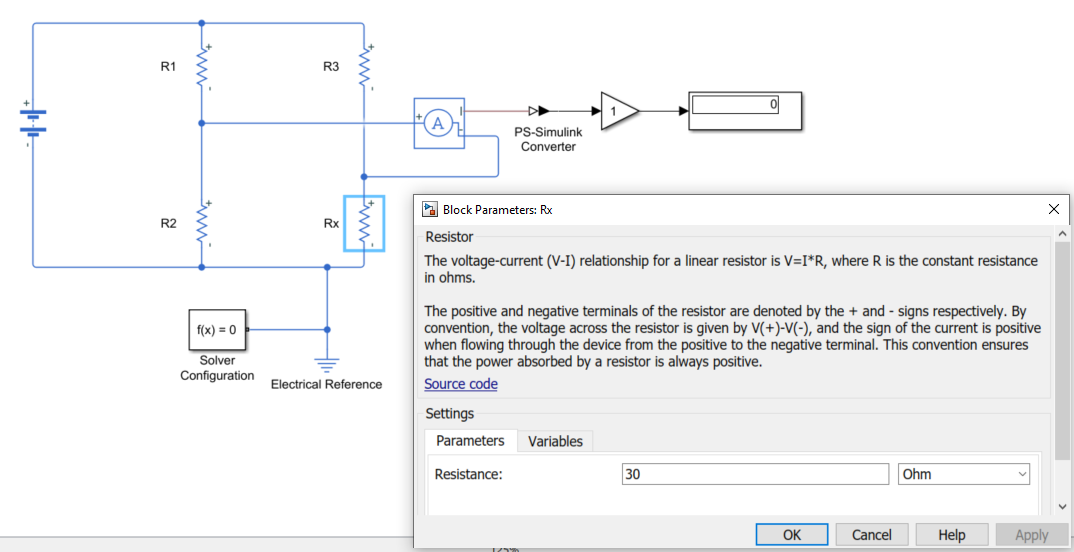

Example 2

model = 'WheatstoneBridge_VariableResistor';
open_system(model)

## Typical applications of bridge-method sensors - Sensors and Transducers

### **Thermistor**

Connect a thermistor to a Wheaston bridge to measure a the temperature of a controlled temperature source.

The Thermistor block represents an NTC thermistor using the B-parameter equation. The resistance at temperature *T* is 


$$R\left(T\right)=R_0 e^{\beta \left(\frac{1}{T}-\frac{1}{T_0 }\right)}$$


where:

- $R_0$ is the nominal resistance at the reference temperature $T_0$.

- $\beta$ is the characteristic temperature constant.

The following equation describes the thermal behavior of the block:


$$Q=K_d t_c \frac{\textrm{dT}}{\textrm{dt}}\;$$


where:

- *Q* is the net heat flow into port A.

- $K_d$ is the **Dissipation factor** parameter value.

- $t_c$ is the **Thermal time constant** parameter value.

- *dT/dt* is the rate of change of the temperature.

To model the thermistor in free space:

- Connect the thermistor to the B port of a Simscape™Convective Heat Transfer block.

- Connect the A port of the Convective Heat Transfer block to a SimscapeIdeal Temperature Source block whose temperature is set to the ambient temperature.

- Set the **Area** parameter of the Convective Heat Transfer block to an approximate area *A*nom.

- Set the **Heat transfer coefficient** parameter of the Convective Heat Transfer block to *K*d/*A*nom.

model = 'Thermistor';
open_system(model)

s = struct with fields:
    v1: 12
    v2: 12


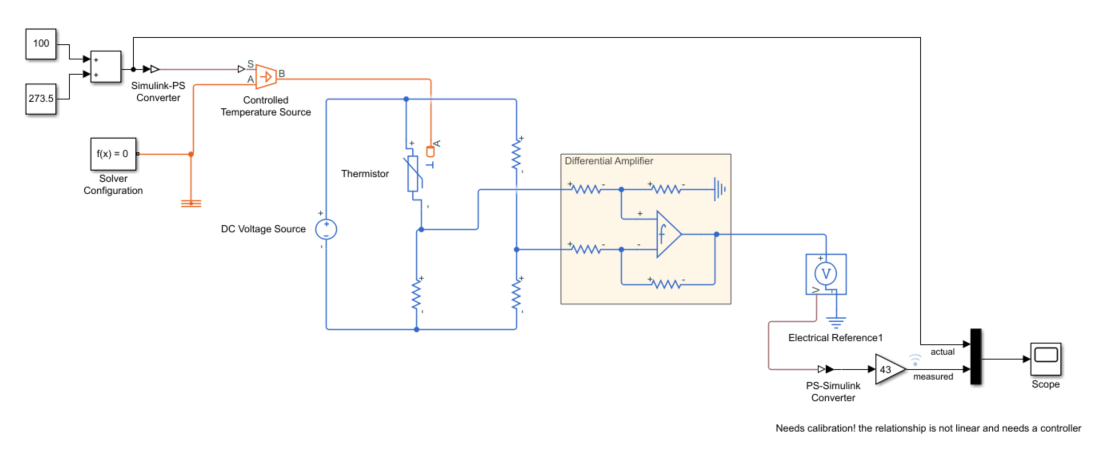

### **Strain Gauge**

% model = 'strain_gauge2';

$$ans = \left(\begin{array}{cc} 12 & 12 \end{array}\right)$$

% open_system(model)

This model shows how to model a strain gauge and measurement amplifier. The strain gauge forms one leg of a Wheatstone bridge, which is connected to a differential amplifier. A second op-amp is then used to both amplify and apply a low-pass filter to the measurement signal. The op-amps are modeled at a system level, with the user specifying parameters such as open-loop bandwidth, gain and maximum slew rate. In this circuit, the dynamics are primarily set by the low-pass filter. The op-amp bandwidth and maximum slew rate have little impact on the step response.

model = 'ee_strain_gauge';
open_system(model)

R = 10

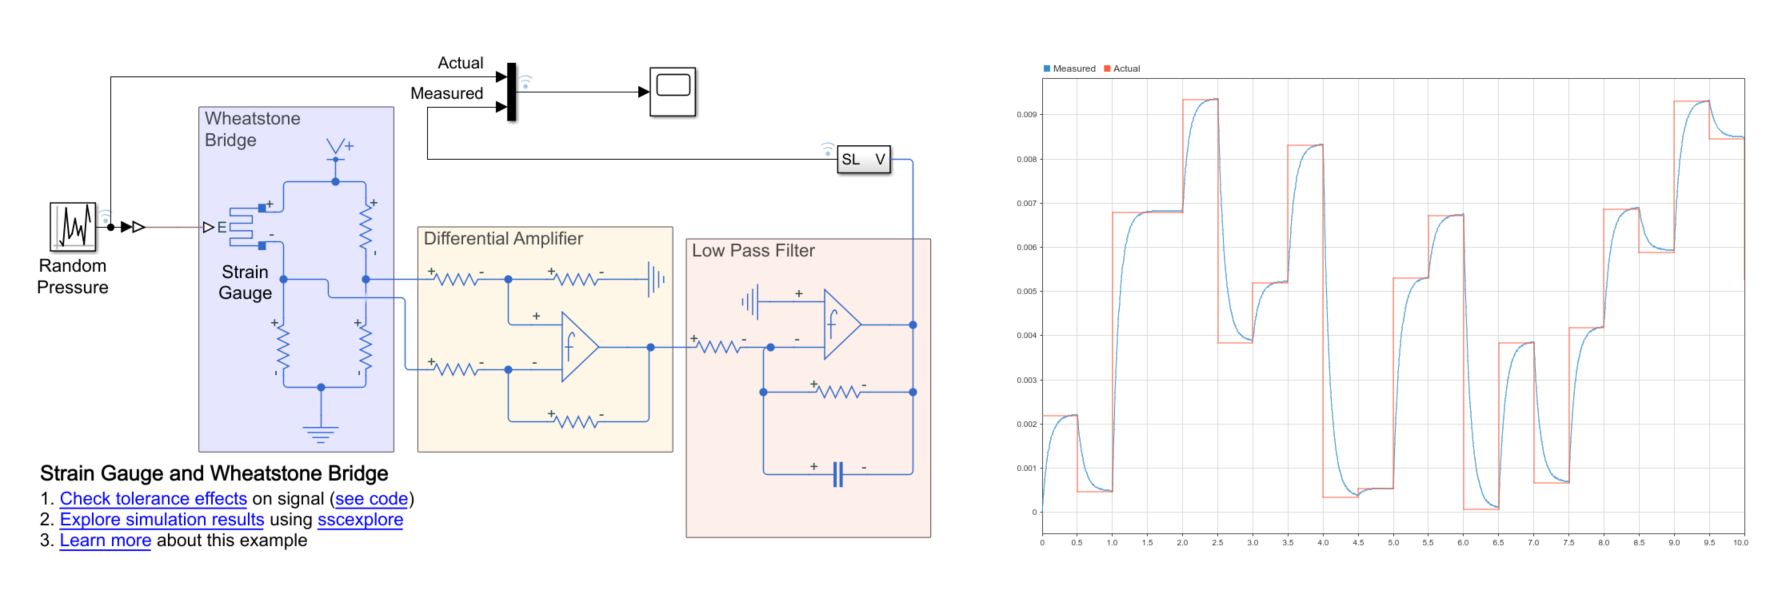

## Additional resources 

**PID controller thermal system**

[https://www.youtube.com/watch?v=80DjildPFAc&list=PLXr7LBwddhmJONrk0FU9N5hZnWHA7Cm7o&index=6](https://www.youtube.com/watch?v=80DjildPFAc&list=PLXr7LBwddhmJONrk0FU9N5hZnWHA7Cm7o&index=6)

**Op-Amp Circuit - Differentiator**

[https://www.mathworks.com/help/physmod/simscape/examples/op-amp-circuit-differentiator.html](https://www.mathworks.com/help/physmod/simscape/examples/op-amp-circuit-differentiator.html)

**Op-Amp Circuit - Inverting Amplifier**

[https://www.mathworks.com/help/physmod/simscape/examples/op-amp-circuit-inverting-amplifier.html?s_tid=srchtitle](https://www.mathworks.com/help/physmod/simscape/examples/op-amp-circuit-inverting-amplifier.html?s_tid=srchtitle)

**Op-Amp Circuit - Noninverting Amplifier**

[https://www.mathworks.com/help/physmod/simscape/examples/op-amp-circuit-noninverting-amplifier.html?s_tid=srchtitle](https://www.mathworks.com/help/physmod/simscape/examples/op-amp-circuit-noninverting-amplifier.html?s_tid=srchtitle)

**Op-Amp with Noise**

[https://www.mathworks.com/help/physmod/sps/examples/op-amp-with-noise.html?s_tid=srchtitle](https://www.mathworks.com/help/physmod/sps/examples/op-amp-with-noise.html?s_tid=srchtitle)

**Triangle Wave Generator**

[https://www.mathworks.com/help/physmod/sps/examples/triangle-wave-generator.html?s_tid=srchtitle](https://www.mathworks.com/help/physmod/sps/examples/triangle-wave-generator.html?s_tid=srchtitle)